TP 4 Signal : Comunication Numérique TP2

M = 16;
N = 512;
sigmab2 = 0.5;

mComplex = const16QAM();
mGray = Gray16QAM();

Simulation Chaîne de transmission

SeqBin = genBin(N)

SeqBin =      0     1     0     1     0     1     1     1     1     1     0     1     0     0     0     1     1     0     1     0     1     0     0     1     1     1     1     1     0     0     0     0     1     0     0     0     0     0     1     0     0     1     1     1     1     0     1     0     0     0



Transmis = mappingGray(SeqBin, mGray, mComplex)

Transmis =   -1.0000 - 1.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i  -3.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 - 1.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i  -3.0000 + 3.0000i  -1.0000 + 1.0000i   3.0000 + 3.0000i  -3.0000 - 3.0000i  -3.0000 + 3.0000i   1.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 - 3.0000i   3.0000 - 1.0000i  -1.0000 + 1.0000i   3.0000 - 1.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i  -1.0000 - 3.0000i   1.0000 + 3.0000i   3.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 + 1.0000i   3.0000 + 1.0000i  -3.0000 - 1.0000i  -1.0000 - 3.0000i   1.0000 + 3.0000i   3.0000 + 3.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i   3.0000 - 3.0000i  -3.0000 - 3.0000i   3.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i  -3.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i   1.0000 - 3.0000i   3.0000 - 3.0000i   3.0000 + 1.0000i  -1.0000 + 3.0000i   3.0000 - 1.0000i



Recu = canalAWGN(Transmis, sigmab2)

Recu =   -0.3742 + 0.6658i  -2.7607 + 0.5282i   1.0498 - 0.6491i  -2.7840 - 1.1222i   3.0264 + 2.5526i   3.3024 - 3.3269i   0.1941 + 0.4846i  -3.8660 - 3.2649i   2.4272 - 3.1729i  -2.5730 + 1.8039i  -0.8761 + 0.8395i   2.0449 + 3.6402i  -2.8623 - 2.2858i  -3.2591 + 2.7568i   0.3953 + 4.2391i  -0.4342 + 1.1893i   0.4595 - 0.6125i   0.4295 - 2.3429i   3.1982 - 2.2557i  -0.6275 + 0.1214i   2.6673 - 0.4703i   0.4258 + 0.7919i  -3.0876 - 2.7400i  -1.3125 - 1.6688i   0.3618 + 2.0568i   2.7672 - 1.2151i  -2.3859 + 2.7688i  -4.3333 + 1.4184i   1.8918 - 0.2688i  -3.3921 - 0.9843i  -2.0911 - 2.4853i   1.2708 + 2.8036i   2.4490 + 2.4432i  -1.1979 + 2.7959i  -1.5050 - 0.5825i   2.8512 - 2.0929i  -3.3523 - 3.1220i   3.7624 + 3.0374i  -2.3794 - 2.7459i   2.1931 - 1.9407i  -4.1320 + 3.6829i  -1.4411 + 0.7482i   1.3710 + 0.2631i  -2.9401 - 2.9289i   3.7809 - 2.1718i   0.4644 - 2.1395i   2.1298 - 3.1362i   3.3453 + 1.0573i  -1.1269 + 2.5482i   3.9710 - 1.8611i



SeqDecid = Decision(Recu, mComplex)

SeqDecid =   -1.0000 + 1.0000i  -3.0000 + 1.0000i   1.0000 - 1.0000i  -3.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 - 3.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i  -3.0000 + 1.0000i  -1.0000 + 1.0000i   3.0000 + 3.0000i  -3.0000 - 3.0000i  -3.0000 + 3.0000i   1.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 - 3.0000i   3.0000 - 3.0000i  -1.0000 + 1.0000i   3.0000 - 1.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i  -1.0000 - 1.0000i   1.0000 + 3.0000i   3.0000 - 1.0000i  -3.0000 + 3.0000i  -3.0000 + 1.0000i   1.0000 - 1.0000i  -3.0000 - 1.0000i  -3.0000 - 3.0000i   1.0000 + 3.0000i   3.0000 + 3.0000i  -1.0000 + 3.0000i  -1.0000 - 1.0000i   3.0000 - 3.0000i  -3.0000 - 3.0000i   3.0000 + 3.0000i  -3.0000 - 3.0000i   3.0000 - 1.0000i  -3.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i   1.0000 - 3.0000i   3.0000 - 3.0000i   3.0000 + 1.0000i  -1.0000 + 3.0000i   3.0000 - 1.0000i



SeqBits = demapGray(SeqDecid, mGray, mComplex)

SeqBits =      0     1     1     1     0     0     1     1     1     1     0     1     0     0     0     1     1     0     1     0     1     0     0     0     1     1     1     1     0     0     0     0     1     0     0     0     0     0     1     1     0     1     1     1     1     0     1     0     0     0


Visualiser la constellation M-QAM et le codage de Gray

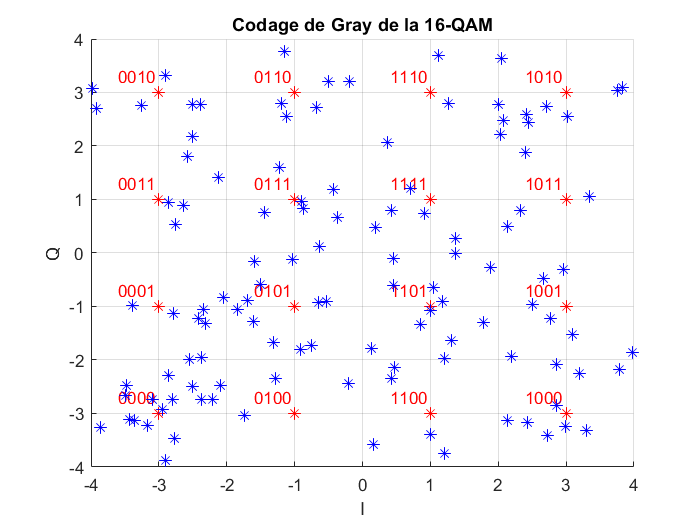

%--------------------------------------------------------
% mComplex : matrice contenant les symboles complexes
% mGray : matrice contenant les codes de Gray

x = real(mComplex(:));
y = imag(mComplex(:));
z = mGray(:);

% new figure
figure

% dessiner les points de la constellation
scatter(x,y,50,'r*');          
axis([-sqrt(M) sqrt(M) -sqrt(M) sqrt(M)]);

% ajouter codes de Gray 
for k = 1 : M
    text(x(k)-0.6,y(k)+0.3,...
        dec2base(z(k),2,log2(M)),'Color',[1 0 0]);
  
end

% parametres figure
title('Codage de Gray de la 16-QAM');
xlabel('I');
ylabel('Q');
grid on


hold on 

scatter(real(Recu),imag(Recu),50,'b*');

hold off

[bitsE, bitsS, anE, anS] = chaine16QAM(N, sigmab2)

bitsE =      1     1     1     1     0     0     0     1     1     0     1     1     1     0     1     0     1     1     0     0     1     0     1     0     0     0     0     0     1     1     0     1     1     1     1     1     0     1     1     0     1     1     1     1     1     1     1     0     0     1


bitsS =      1     1     1     1     0     0     0     1     1     0     0     1     1     0     1     0     1     1     0     0     1     0     1     0     0     0     0     0     1     1     0     1     0     1     1     1     0     1     1     0     1     1     1     1     1     1     1     0     0     1


anE =    1.0000 + 1.0000i  -3.0000 - 1.0000i   3.0000 + 1.0000i   3.0000 + 3.0000i   1.0000 - 3.0000i   3.0000 + 3.0000i  -3.0000 - 3.0000i   1.0000 - 1.0000i   1.0000 + 1.0000i  -1.0000 + 3.0000i   1.0000 + 1.0000i   1.0000 + 3.0000i  -1.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i   1.0000 - 3.0000i   3.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 + 3.0000i  -1.0000 - 3.0000i   3.0000 + 1.0000i  -3.0000 + 3.0000i  -3.0000 + 3.0000i  -1.0000 + 3.0000i  -3.0000 - 1.0000i   3.0000 + 3.0000i  -3.0000 - 1.0000i  -1.0000 + 1.0000i  -3.0000 + 3.0000i   3.0000 - 1.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i  -1.0000 - 3.0000i  -3.0000 - 3.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   3.0000 - 1.0000i   3.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i   3.0000 - 1.0000i   1.0000 - 3.0000i   3.0000 + 1.0000i   3.0000 + 1.0000i  -1.0000 + 3.0000i  -3.0000 + 3.0000i   3.0000 - 1.0000i  -1.0000 - 1.0000i  -3.0000 - 1.0000i  -3.0000 + 1.0000i


anS =    1.0000 + 1.0000i  -3.0000 - 1.0000i   3.0000 - 1.0000i   3.0000 + 3.0000i   1.0000 - 3.0000i   3.0000 + 3.0000i  -3.0000 - 3.0000i   1.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 + 3.0000i   1.0000 + 1.0000i   1.0000 + 3.0000i  -1.0000 - 1.0000i   1.0000 + 1.0000i  -3.0000 - 3.0000i   1.0000 - 3.0000i   1.0000 - 1.0000i   3.0000 + 3.0000i   3.0000 + 3.0000i  -1.0000 - 3.0000i   3.0000 + 1.0000i  -3.0000 + 1.0000i  -3.0000 + 3.0000i  -1.0000 + 3.0000i  -3.0000 + 1.0000i   3.0000 + 3.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i  -3.0000 + 3.0000i   3.0000 - 1.0000i  -3.0000 - 3.0000i   3.0000 - 3.0000i   1.0000 - 3.0000i  -3.0000 - 3.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   3.0000 - 1.0000i   3.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i   3.0000 - 1.0000i   3.0000 - 3.0000i   3.0000 + 1.0000i   3.0000 + 1.0000i  -1.0000 + 3.0000i  -3.0000 + 3.0000i   3.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 - 1.0000i  -3.0000 + 1.0000i


Calcule nombre et taux d'erreur

NBerreurBin = sum(abs(bitsE-bitsS))

NBerreurBin = 33

TauxErreurBin = NBerreurBin/N

TauxErreurBin = 0.0645